# Generalized Large shock SV


clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.


percentiles = [10, 50, 90];
prctilesFunc = @(x) prctile(x, percentiles, 2);
extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

defaultColors = get(0, "defaultAxesColorOrder");


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("covid.csv");

estimStart = datex.m(1990,1);
estimEnd = datex.m(2021,5);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["UNEMP","EMP","PCE","PCE_SERV","PCE_price","PCE_SERV_price","PCE_CORE_price"], ...
    units="", ...
    exogenous=[], ...
    order=13, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=12 ...
    ...
);

dataH = model.DataHolder(meta, inputTbx);

estimatorR = estimator.GenLargeShockSV(meta, ...
    AutoRegression = 1, ...
    Lambda1 = 0.120645548495565, Lambda3 = 2, ... %Minnesota hyperparams on B
    Mult0 = [20, 10, 5], ScaleMult = [1, 1, 1], ShapeMult = [1, 1, 1], ... %independent scaling factor hyper params
    PropStdMult = [5, 5, 5],...
    MultAR0 = 0.2, AlphaMultAR = 3.035685473974237, BetaMultAR = 1.508921347750411, ... % scaling factor AR param hyper params
    PropStdAR = [1],...
    Turningpoint = datex.m(2020,3)); %Date for the first multiplier

modelR = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , stabilityThreshold=Inf ...
);

modelR.Estimator.Settings

ans =   GenLargeShockSV with properties:

                     Mult0: [20 10 5]
                 ScaleMult: [1 1 1]
                 ShapeMult: [1 1 1]
               PropStdMult: [5 5 5]
                   MultAR0: 0.2000
               AlphaMultAR: 3.0357
                BetaMultAR: 1.5089
                 PropStdAR: 1
              Turningpoint: 2020-03
                    Burnin: 0
                 Exogenous: [7×1 logical]
            BlockExogenous: 0
            Autoregression: [7×1 double]
                   Lambda1: 0.1206
                   Lambda2: 0.5000
                   Lambda3: 2
                   Lambda4: [7×1 double]
                   Lambda5: 1.0000e-03
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000


## Identification, sampling SVAR

identChol = identifier.Cholesky(order=[]);

modelS = model.Structural(reducedForm=modelR, identifier=identChol);
modelS.initialize();
info1 = modelS.presample(10000);


 Presampling model.Structural (GenLargeShockSV) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 




modelS.Presampled{1}.sf

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



modelS.Presampled{1}.Sigma_avg

ans =     0.0214   -0.0101   -0.0138   -0.0111   -0.0001   -0.0002    0.0002
   -0.0101    0.0197    0.0220    0.0142    0.0020    0.0008    0.0004
   -0.0138    0.0220    0.1507    0.0568    0.0004    0.0044    0.0017
   -0.0111    0.0142    0.0568    0.0601   -0.0032   -0.0008   -0.0009
   -0.0001    0.0020    0.0004   -0.0032    0.0255    0.0086    0.0072
   -0.0002    0.0008    0.0044   -0.0008    0.0086    0.0108    0.0075
    0.0002    0.0004    0.0017   -0.0009    0.0072    0.0075    0.0076


modelS.Presampled{1}.sf

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


modelS.Presampled{1}.Sigma_t{1,:}

ans =     0.0214   -0.0101   -0.0138   -0.0111   -0.0001   -0.0002    0.0002
   -0.0101    0.0197    0.0220    0.0142    0.0020    0.0008    0.0004
   -0.0138    0.0220    0.1507    0.0568    0.0004    0.0044    0.0017
   -0.0111    0.0142    0.0568    0.0601   -0.0032   -0.0008   -0.0009
   -0.0001    0.0020    0.0004   -0.0032    0.0255    0.0086    0.0072
   -0.0002    0.0008    0.0044   -0.0008    0.0086    0.0108    0.0075
    0.0002    0.0004    0.0017   -0.0009    0.0072    0.0075    0.0076


modelS.Presampled{1}.Sigma_t{362,:}

ans =     0.0214   -0.0101   -0.0138   -0.0111   -0.0001   -0.0002    0.0002
   -0.0101    0.0197    0.0220    0.0142    0.0020    0.0008    0.0004
   -0.0138    0.0220    0.1507    0.0568    0.0004    0.0044    0.0017
   -0.0111    0.0142    0.0568    0.0601   -0.0032   -0.0008   -0.0009
   -0.0001    0.0020    0.0004   -0.0032    0.0255    0.0086    0.0072
   -0.0002    0.0008    0.0044   -0.0008    0.0086    0.0108    0.0075
    0.0002    0.0004    0.0017   -0.0009    0.0072    0.0075    0.0076


modelS.Presampled{1}.Sigma_t{363,:}

ans =     8.2863   -3.9139   -5.3350   -4.2834   -0.0282   -0.0686    0.0669
   -3.9139    7.6511    8.5355    5.5196    0.7694    0.2968    0.1596
   -5.3350    8.5355   58.4049   22.0348    0.1462    1.6914    0.6630
   -4.2834    5.5196   22.0348   23.2870   -1.2526   -0.3222   -0.3505
   -0.0282    0.7694    0.1462   -1.2526    9.8894    3.3177    2.8022
   -0.0686    0.2968    1.6914   -0.3222    3.3177    4.1750    2.8978
    0.0669    0.1596    0.6630   -0.3505    2.8022    2.8978    2.9650


sqrt(modelS.Presampled{1}.Sigma_t{363,:}./modelS.Presampled{1}.Sigma_t{362,:})

ans =    19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877
   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877   19.6877



modelS.Presampled{1}.D

ans =     0.1462   -0.0691   -0.0941   -0.0756   -0.0005   -0.0012    0.0012
         0    0.1224    0.1268    0.0737    0.0159    0.0056    0.0040
         0         0    0.3546    0.1139   -0.0048    0.0100    0.0037
         0         0         0    0.1896   -0.0206   -0.0130   -0.0081
         0         0         0         0    0.1575    0.0524    0.0445
         0         0         0         0         0    0.0879    0.0567
         0         0         0         0         0         0    0.0486


## Structural shock IRFs



respTbx = modelS.simulateResponses();
respTbx = tablex.apply(respTbx, extremesFunc);
respTbx = tablex.flatten(respTbx);

respTbx

respTbx = 25×49 timetable
     Time         UNEMP___shock1           UNEMP___shock2             UNEMP___shock3             UNEMP___shock4            UNEMP___shock5            UNEMP___shock6             UNEMP___shock7              EMP___shock1              EMP___shock2             EMP___shock3              EMP___shock4               EMP___shock5                EMP___shock6                EMP___shock7               PCE___shock1              PCE___shock2            PCE___shock3            PCE___shock4              PCE___shock5               PCE___shock6              PCE___shock7           PCE_SERV___shock1

## Unconditional forecast

### Start forecast in COVID period

setting up the sample

fcastStart1 = datex.shift(modelS.Meta.EstimationEnd, -15);
fcastEnd1 = datex.shift(modelS.Meta.EstimationEnd, -5);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);


Run forecast and show error band

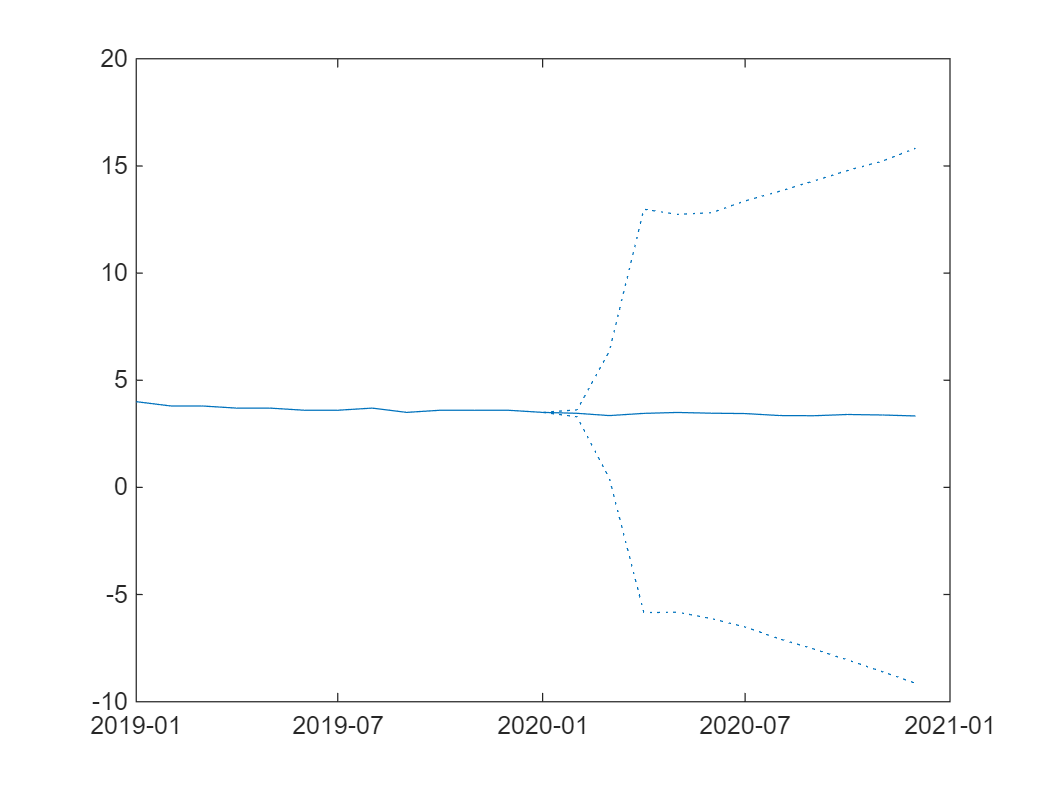

fcastTbx1 = modelS.forecast(fcastSpan1);
fcastTbx1 = tablex.apply(fcastTbx1, prctilesFunc);

tablex.plot( ...
    fcastTbx1, "UNEMP", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);

### Start forecast at the end of the sample

setting up the sample, start forecast

fcastStart2 = datex.shift(modelS.Meta.EstimationEnd, -4);
fcastEnd2 = datex.shift(modelS.Meta.EstimationEnd, +6);
fcastSpan2 = datex.span(fcastStart2, fcastEnd2);


Standard

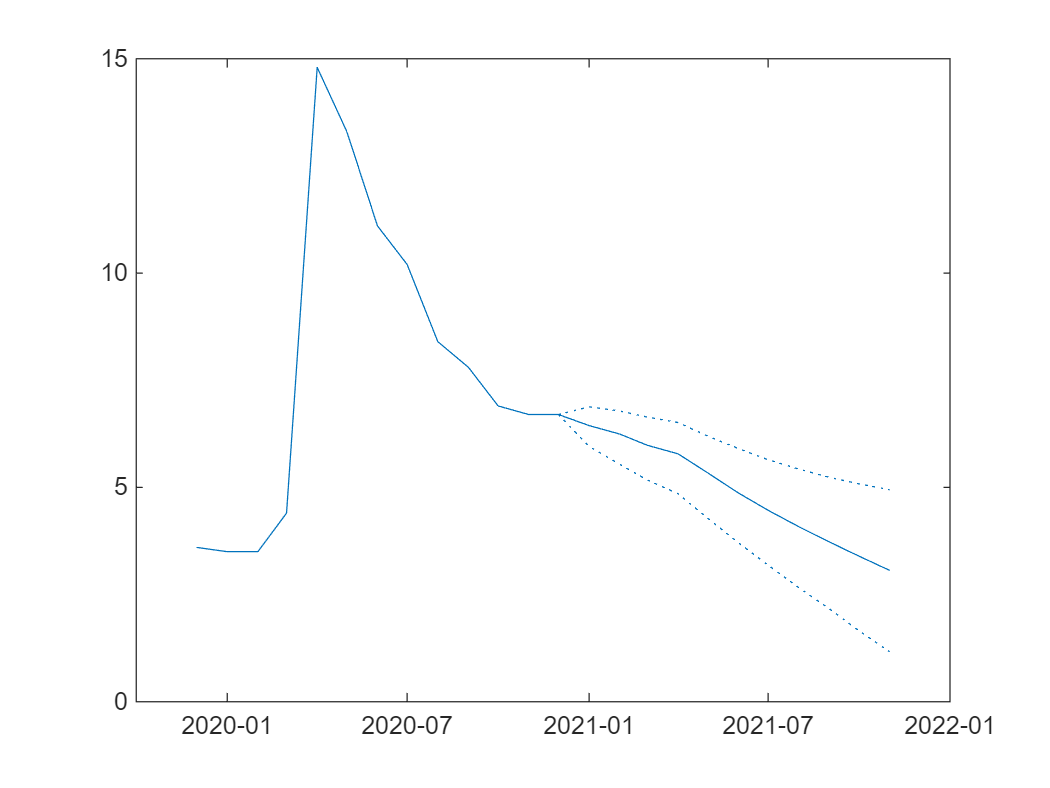

fcastTbx2 = modelS.forecast(fcastSpan2);
fcastTbx2 = tablex.apply(fcastTbx2, prctilesFunc);

tablex.plot( ...
    fcastTbx2, "UNEMP", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);